# Introduction to MATLAB and Coding with Arrays

### By: Arnaldo Rodriguez-Gonzalez

This Live Script is designed as a helpful first step for you to learn the basics of coding in MATLAB and on how to manipulate arrays of numbers, the backbone of all scientific computing.

## Arrays of Numbers

An ***array of numbers*** is just a fancy term for a list of numbers; you may have heard terms like "vectors" and "matrices" to refer to the same idea. For example, an array of numbers you might see in a textbook or lecture notes may look something like:

Example 1: $$\left[1\ 2\ 3\ 4\ 5\right]$

or:

Example 2: $\left[\matrix{1 \cr 2 \cr 3 \cr 4 \cr 5} \right]$

When the array resembles a list like in the two examples above—in both cases, a "one-dimensional" array of numbers—these arrays are often referred to as "vectors" in some engineering textbooks (although the terminology is not technically always correct). 

Both of the arrays above can be constructed in MATLAB very easily. For example, type 

into the MATLAB command window—that's the window with the >> on it—and press Enter. You should see MATLAB saying something like 

back at you; that's MATLAB letting you know that it stored the array correctly in its memory, and called it by "ans" by default. These names, which you can use to call back previous arrays you've inputted, are in MATLAB parlance called ***variables***.

## Variables

Right now, if you look at your workspace, you should see a single entry; the variable "name" `ans`, with the number array you inputted in as its "value". If you type `ans,` this variable's name, into the command window, you'll get back the array of numbers you inputted before. Go ahead and try it now!

In general, variables are a combo of name/stored content that you can exploit to easily manipulate stored number arrays without having to retype everything all the time. Anything you enter into the command window will be stored by MATLAB into a "default" variable named `ans, `so it's usually good to store everything you plan to use later in variables you define yourself. For example, try entering

into the Command Window; this will create the variable with name `x` and "value" `[1 2 3 4 5],` and you'll see the new variable show up in your workspace accordingly. If you ever want to see the value of a given variable, just type its name into the Command Window and the value will pop up.

## Arrays of Numbers, Continued

The array we named `ans` and later `x` is a horizontal array of numbers. If we wanted to make a vertical column of numbers, like the one in Example 2, we can use the following MATLAB notation to input them:

If you copy/paste this into the Command Window and hit Enter, the `ans` variable will get overwritten with this new array, which should show up as a vertical column of numbers. The semi-colon ; is effectively indicating a "line break" in the array, a trick we'll exploit in a second. 

To store this column of numbers so that it doesn't get erased later, we can exploit how variables work and type the following line into the Command Window:

In MATLAB terms, this line is saying that the left-hand side of the equation—a new variable `y` which we've just invented—is equal in value to the right-hand side of the equation, the variable `ans,` which we previously defined as a column of numbers. *In MATLAB, you can only define new variables this way by putting them on the left-hand side of the equation!*

Now suppose we wanted to input a two-dimensional array of numbers—a matrix—into MATLAB. An example of such a matrix is below:

Example 3: $\left[\matrix{ 1 & 2 \cr 3 &4} \right]$

We can enter matrices into MATLAB by using a combination of spaces and semi-colons in the appropriate locations. To input the matrix in Example 3, you can use the following code—I've taken the liberty of directly "naming" it as a new variable `z`.

The space separates the numbers horizontally, and the semi-colon "starts a new line" of horizontal numbers.

#### Quick Test 1: 

Using MATLAB syntax, define and enter the following variable/array into the slot below, making sure to use the same variable name:


$$w = \left[\matrix{ 1 & 2 & 3 \cr 6 & 5 & 4 \cr 9 & 7 & 8} \right]$$


Once you've entered it into the slot below, press the button to check if you did it correctly. What you inputted will also be displayed below in either case, to help you troubleshoot if you got it wrong.

w = [1 2 3; 6 5 4; 9 7 8]

w =      1     2     3
     6     5     4
     9     7     8


 
if w == [1 2 3; 6 5 4; 9 7 8]
    disp("Congratulations, you defined the array correctly!")
else
    disp("You got something wrong; try again!")
end

Congratulations, you defined the array correctly!


## Large Arrays of Numbers

Most of the time in scientific computing, you'll need to deal with arrays of numbers that are so large that typing them out directly is impossible. For example, you may need a horizontal array consisting of every integer from 1 to 100. Rather than actually typing it out, you can do it using the following syntax:

The colons : are indicating that the array is a list that goes from 1 to 100 in increments of 1. Similarly, the following code will generate an array that goes from 0 to 1 in steps of 0.1:

Often times, you'll want something described the following way: "An evenly-spaced array of 1000 numbers between 0 to 1". To do this, the following line of code can be used:

The `linspace` function/command is very useful for making large arrays of numbers; we'll use it again as we go further along the tutorial.

## Manipulating Arrays of Numbers

Now that you know how to input number arrays, you have to learn how to manipulate them. As a general rule, if you want to perform a mathematical operation on each number in an array—what MATLAB calls an "element-wise operation"—the only "trick" to doing so in MATLAB is to sometimes put a dot . before the given operation.

Let's use `x = [1 2 3 4 5]` as our test example. To add or subtract 2 to every number in `x`, just use the following, no dot required:

To multiply or divide each number in `x` by 2, you can use the dot or no dot. (I prefer to use it, just in case.)

To square each number in `x`, you have to use the dot; trying to do so without the dot will make MATLAB toss out an error message (try it!).

Parentheses are a convenient way to tell MATLAB which operations you want to perform first; MATLAB will do the stuff inside parentheses first. For example, the following two lines of code return different results because the order of operations is executed differently:

#### Quick Test 2: 

Using MATLAB syntax and the definition of `x = [1 2 3 4 5]`, calculate the following number array `v` using element-wise operations:


$$v =\frac{(x+2)^3}{4}$$


Once you've entered the result into MATLAB as the variable `v`, press the button below to check if you did it correctly. Remember to enter `x` into your workspace first if you are defining it relative to `x`!

v = ((x+2).^3)/4

v =     6.7500   16.0000   31.2500   54.0000   85.7500


 

if v == ((x+2).^3)/4
    disp("Congratulations, you defined the array correctly!")
else
    disp("You got something wrong; try again!")
end

Congratulations, you defined the array correctly!


In my head, the operations I've shown you are the most natural way to manipulate number arrays—by performing the same operation on every number in the array, what MATLAB calls "element-wise operations"—but it is not the default way. For MATLAB, the mathematical operations `+, -, *, /, ^ `are *matrix algebra* operations, and are interpreted using matrix algebra rules. For example, the output of the two following lines of code will not be the same:

This is because the multiplication used here, with no dot, is matrix multiplication, which depends on both the structure of the arrays and the ordering of the arrays in the operation. If you're not familiar with matrix algebra/operations, feel free to take a break to get a reminder/look up a resource on matrix operations specifically. For what it's worth, most errors by beginner users of MATLAB tend to be because of miscalculations/unfamiliarity with matrix algebra; they were certainly the majority of my errors when I started out coding! 

## Plotting Relationships Between Arrays

Now we're getting to the cool stuff. A big application of manipulating arrays is to plot mathematical functions, or approximations to them; let's test this out by considering `x` as we defined before. 

The following self-contained snippet of code will generate a plot of `u`—a new variable consisting of the square of every number in the array `x`—on the vertical axis, as a function of `x` on the horizontal axis. In other words, it will associate the 1st element of `x` with the 1st element of `u` and so on, generating a plot based on this connection. Press the button below to run this snippet and see the plot.

x = [1 2 3 4 5]

x =      1     2     3     4     5


u = x.^2

u =      1     4     9    16    25


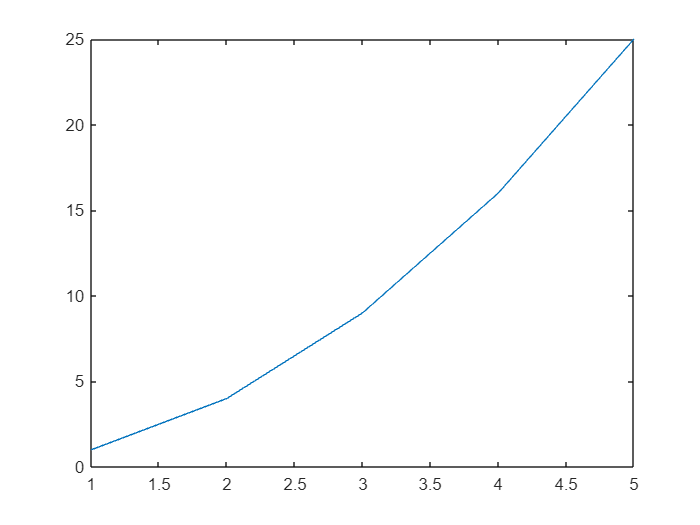

plot(x,u)

Although this is the default MATLAB plot format, it is a bit misleading. You see, the blue lines in between the values at x = 1, 2, 3, 4, and 5 are not "real"; we have no data for any numbers between 1 and 2, or 2 and 3, etcetera. 

To get the "real" plot, we have to add a little modifier to the code snippet above:

x = [1 2 3 4 5]

x =      1     2     3     4     5


u = x.^2

u =      1     4     9    16    25


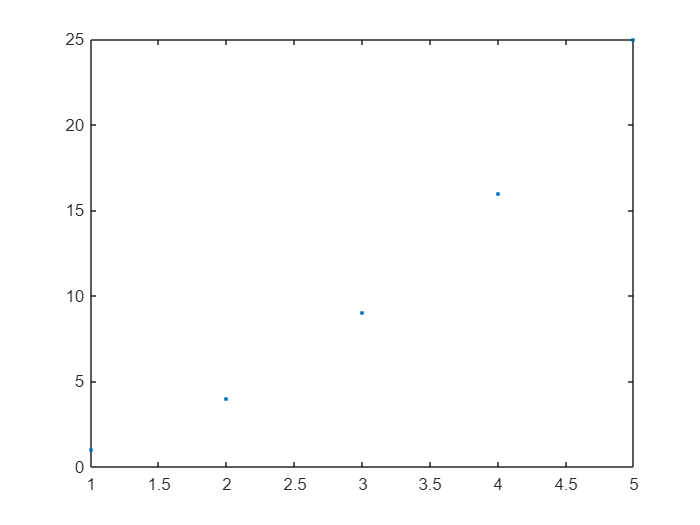

plot(x,u,'.')

That being said, if the array is sufficiently "dense", the plot will capture the function quite well no matter what; take a look at what happens when we define a new `x` consisting of a thousand evenly spaced points between 1 and 5 using the `linspace` command we saw earlier, and define `u` relative to `x` the same way:

x = linspace(1,5,1000)

x =     1.0000    1.0040    1.0080    1.0120    1.0160    1.0200    1.0240    1.0280    1.0320    1.0360    1.0400    1.0440    1.0480    1.0521    1.0561    1.0601    1.0641    1.0681    1.0721    1.0761    1.0801    1.0841    1.0881    1.0921    1.0961    1.1001    1.1041    1.1081    1.1121    1.1161    1.1201    1.1241    1.1281    1.1321    1.1361    1.1401    1.1441    1.1481    1.1522    1.1562    1.1602    1.1642    1.1682    1.1722    1.1762    1.1802    1.1842    1.1882    1.1922    1.1962


u = x.^2

u =     1.0000    1.0080    1.0161    1.0242    1.0323    1.0404    1.0486    1.0568    1.0651    1.0734    1.0817    1.0900    1.0984    1.1068    1.1153    1.1237    1.1322    1.1408    1.1493    1.1579    1.1666    1.1752    1.1839    1.1927    1.2014    1.2102    1.2190    1.2279    1.2368    1.2457    1.2547    1.2637    1.2727    1.2817    1.2908    1.2999    1.3091    1.3182    1.3275    1.3367    1.3460    1.3553    1.3646    1.3740    1.3834    1.3928    1.4023    1.4118    1.4213    1.4309


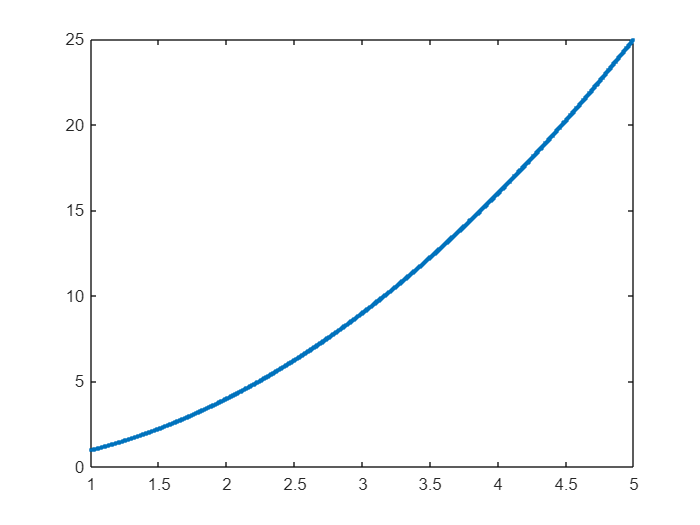

plot(x,u,'.')

Finally, there are a couple of commands you can use to customize your plots and make them look a lot better; adding titles, axes labels, and grids. There's a lot you can do, so I won't spend time talking about it now; but here's an example of how to snazz up the previous plot so it looks a lot better.

x = linspace(1,5,1000)

x =     1.0000    1.0040    1.0080    1.0120    1.0160    1.0200    1.0240    1.0280    1.0320    1.0360    1.0400    1.0440    1.0480    1.0521    1.0561    1.0601    1.0641    1.0681    1.0721    1.0761    1.0801    1.0841    1.0881    1.0921    1.0961    1.1001    1.1041    1.1081    1.1121    1.1161    1.1201    1.1241    1.1281    1.1321    1.1361    1.1401    1.1441    1.1481    1.1522    1.1562    1.1602    1.1642    1.1682    1.1722    1.1762    1.1802    1.1842    1.1882    1.1922    1.1962


u = x.^2

u =     1.0000    1.0080    1.0161    1.0242    1.0323    1.0404    1.0486    1.0568    1.0651    1.0734    1.0817    1.0900    1.0984    1.1068    1.1153    1.1237    1.1322    1.1408    1.1493    1.1579    1.1666    1.1752    1.1839    1.1927    1.2014    1.2102    1.2190    1.2279    1.2368    1.2457    1.2547    1.2637    1.2727    1.2817    1.2908    1.2999    1.3091    1.3182    1.3275    1.3367    1.3460    1.3553    1.3646    1.3740    1.3834    1.3928    1.4023    1.4118    1.4213    1.4309


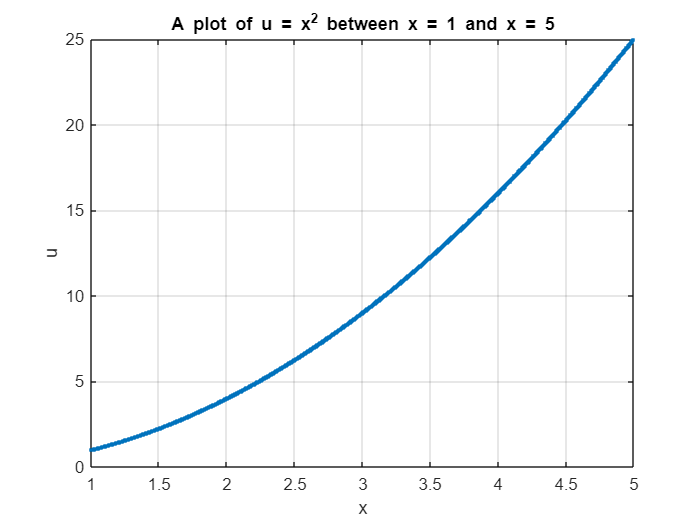

plot(x,u,'.')
grid on
xlabel('x')
ylabel('u')
title('A plot of u = x^2 between x = 1 and x = 5')

You are not restricted to just plotting simple functions derived from basic arithmetic in MATLAB; you can use pre-defined MATLAB functions as well. For example, here's what sin(x)/x would look like between x = 0.01 and x = 20, and how you would plot it:

x = linspace(0.01,20,1000)

x =     0.0100    0.0300    0.0500    0.0700    0.0900    0.1101    0.1301    0.1501    0.1701    0.1901    0.2101    0.2301    0.2501    0.2701    0.2901    0.3102    0.3302    0.3502    0.3702    0.3902    0.4102    0.4302    0.4502    0.4702    0.4902    0.5103    0.5303    0.5503    0.5703    0.5903    0.6103    0.6303    0.6503    0.6703    0.6903    0.7104    0.7304    0.7504    0.7704    0.7904    0.8104    0.8304    0.8504    0.8704    0.8904    0.9105    0.9305    0.9505    0.9705    0.9905


u = sin(x)./x

u =     1.0000    0.9998    0.9996    0.9992    0.9986    0.9980    0.9972    0.9963    0.9952    0.9940    0.9927    0.9912    0.9896    0.9879    0.9860    0.9840    0.9819    0.9797    0.9773    0.9748    0.9722    0.9694    0.9666    0.9636    0.9604    0.9572    0.9538    0.9503    0.9467    0.9429    0.9391    0.9351    0.9310    0.9268    0.9224    0.9180    0.9134    0.9088    0.9040    0.8991    0.8941    0.8890    0.8837    0.8784    0.8730    0.8675    0.8618    0.8561    0.8503    0.8443


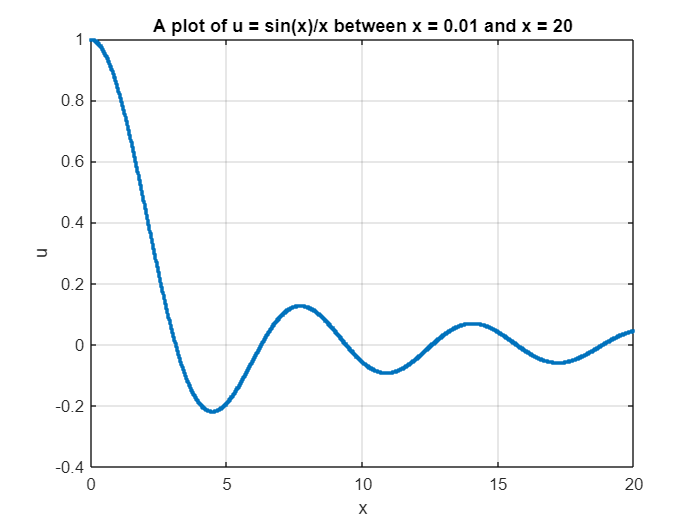

plot(x,u,'.')
grid on
xlabel('x')
ylabel('u')
title('A plot of u = sin(x)/x between x = 0.01 and x = 20')

Some other functions that MATLAB uses for common mathematical operations are `exp(x)` for $e^x$, `sqrt(x)` for $\sqrt{x}$, and `factorial(x)` for $x!$. 

With enough practice, you'll be able to make cool 3-D plots like this in no time:

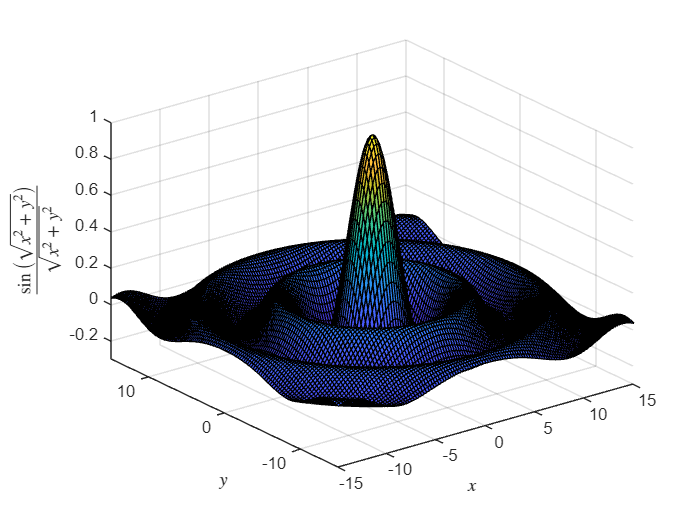

[X1,Y1] = meshgrid(-15:0.25:15,-15:0.25:15);
z1 = sinc(sqrt((x1/pi).^2+(y1/pi).^2));
surf(x1,y1,z1);
axis([-15 15 -15 15 -0.3 1])
xlabel('$x$',Interpreter = 'Latex')
ylabel('$y$',Interpreter = 'Latex')
zlabel('$\frac{\sin\left(\sqrt{x^2 + y^2}\right)}{\sqrt{x^2 + y^2}}$',Interpreter = 'Latex')

## Finding Parts of Arrays

Let's suppose that, given some array that's already defined within MATLAB, you'd like to find the value of a specific number inside of the array. Using `x = [1, 2, 3, 4, 5]` again, you can output the third number in `x` by simply writing `x(3)` in the Command Window and hitting Enter.

For matrices, you index by first listing the row number and then the column number inside the parenthesis. For $w = \left[\matrix{ 1 & 2 & 3 \cr 6 & 5 & 4 \cr 9 & 7 & 8} \right]$, you would find the value in the second row and third column, which is 4, by typing `w(2,3)`.

You can also pull out parts of an array that are themselves arrays; for example, the following code will return the third, fourth, and fifth numbers in `x` as its own array of numbers `[3,4,5].`

In this case, the argument inside the parenthesis—`[3,4,5]`—is an argument that asks for the third, fourth, and fifth element in the array `x`.

#### Quick Test 3: 

Using MATLAB syntax and the matrix shown below, use indexing to find the value in the bottom row and first column of the following matrix:


$$s = \left[\matrix{ 10 & 43 & 65 \cr 90 & 5 & 57 \cr 0.1 & 24 & 7} \right]$$


You do not need to define/enter the matrix `s` in this exercise. Once you've entered the code into the slot below, press the button to check if you did it correctly. What you inputted will also be displayed below in either case, to help you troubleshoot if you got it wrong.

s = [10 43 65; 90 5 57; 0.1 24 7];
s2 = s(3,1)

s2 = 0.1000

 
if s2 == s(3,1)
    disp("Congratulations, you found the right value!")
else
    disp("You got something wrong; try again!")
end

Congratulations, you found the right value!


Another neat application of this is called ***logical indexing***; you can find parts of arrays that satisfy some condition or logical statement. To do so, simply write the statement (with the correct formatting) inside of the indexing parentheses. For example, suppose `r` was an array of 50 evenly-spaced numbers between 0 and $\pi$; we could output an array that contains only the values of `r` that are larger than 3 with the following code, which also defines `r`:

This is a very useful trick, in my opinion; don't forget about it as you learn to code!

## Coding 101: Loops

Now let's transition into general coding techniques. Often, coding uses the notion of a ***loop***; a statement that MATLAB repeatedly executes until some condition, usually related to a variable, is satisfied. An example of such a loop is a ***while loop***, which occurs while an associated variable satisfies a condition. Here's a concrete simple example of a while loop:

counter = 1

counter = 1

while counter < 5
    disp('Loop is currently ongoing!')
    counter = counter + 1
end

Loop is currently ongoing


counter = 2

Loop is currently ongoing


counter = 3

Loop is currently ongoing


counter = 4

Loop is currently ongoing


counter = 5

disp('Loop has finished!')

Loop has finished!


To decode what's going on up there; the first line defines a variable `counter` that is just the number 1. Then the loop begins; MATLAB checks if `counter` is smaller than 5, which it is, and thus proceeds to run the contents of the loop. MATLAB displays the text `Loop is currently ongoing!` and, in the next line, increases the previously stored value of counter (1) by 1 such that now `counter = 2`. Once it hits `end`, the end of the loop, it goes back to the start and checks if the while statement—if `counter` is smaller than 5—remains true, and if so, repeats the contents of the loop. Once `counter` increases to 5 due to repeated looping, the while statement will be false, and the loop will terminate. The last line of code, located outside the loop, just indicates this.

A more common variant of loop that is used in MATLAB is the ***for loop***; in it, the loop is run for a given number of cases, indexed by a variable that distinguishes each case. Here's a for loop version of the previous loop to easily notice the differences;

for counter = [1 2 3 4 5]
    disp('Loop is currently ongoing!')
    counter
end

Loop is currently ongoing!


counter = 1

Loop is currently ongoing!


counter = 2

Loop is currently ongoing!


counter = 3

Loop is currently ongoing!


counter = 4

Loop is currently ongoing!


counter = 5

disp('Loop has finished!')

Loop has finished!


Here, the statement `for counter = [1 2 3 4 5]` is interpretable as a list of cases; the variable `counter` will take the value 1 on the first run of the loop, then 2, and so on until it reaches the last number on the list, 5. The two lines inside the for loop just display the fact the loop is ongoing, and the current value of `counter` is printed out via simply inputting its name on every iteration of the loop. Nothing needs to be done inside the loop to alter the value of `counter` on every iteration of the loop; the for statement already takes care of that. Also note that we never needed to define `counter` outside of the loop; even if we had, it would get overwritten by the definition in the for statement.

## Coding 101: If/Else Statements

Another common feature of most scripts/algorithms are ***if/else statements***, which are pieces of code which only execute if a given statement is true or false. Unlike loops, they only run once (unless you put them inside a loop, of course). For example, in the box below, write down a value for the variable `t`; depending on which value you enter, the snippet of code will generate a different output.

t = 7;

if t > 5
    disp('The value for the variable t you picked is larger than 5!')
else
    disp('The value for the variable t you picked is smaller or equal to 5!')
end

The value for the variable t you picked is larger than 5!


## Writing Scripts and Functions

Rather than inputting lines of code one-by-one into the Command Window, coders will write each line into a text file called a ***script*** and then "run" the file, which really just means telling MATLAB to read each line of input sequentially from top to bottom. Sometimes, you want said scripts to take a variable (or set of variables) as input and then have it execute a complex set of coded instructions and return some simple output, without necessarily caring about the in-between steps and variables; for this, you can use what MATLAB calls ***functions***. Functions in MATLAB are ubiquitious, and it comes pre-loaded with a massive amount of them—`linspace` is one of them, for example. Other very useful ones include `max`, `sort`, `fzero,` `ode45`, and many many more. You can make your own as well by following the proper format, which is usually pre-generated in the text file when you ask MATLAB to create a new function in the toolbar menu. 

Why make functions? It is good practice to try to make code modular; if you know a given piece of your code is working perfectly, separating that piece out as an independent function makes sense. And, by separating it out into its own function, you can use that little snippet of code in other scripts without having to copy/paste all the time.

## Commentary on Coding in MATLAB

Criticisms of MATLAB include that it is slow (a valid criticism if and only if you are doing decently hardcore scientific computing), proprietary (a valid criticism), and that most desired coding outcomes can be generated via use of an extroardinary large library of pre-defined functions rather than via "base code" (this criticism is idiotic; ask me about it). MATLAB's extensive and uniform library of functions is its greatest strength, and using it is an enormous advantage both for writing code in MATLAB and to prototype algorithms you may choose to write in other programming languages. Things that may take 100 lines of code in other languages will take 5-10 in MATLAB!

Chances are that, for anything you may have to do in MATLAB as part of your training as an engineer, someone else will have done a decent chunk of it before; and searching the Internet to see what other folks have coded to solve the problem you're trying to solve in an excellent first step towards making your own solution to an engineering problem (with proper attribution, of course). And if you ever see the use of a strange function/command that you may not have seen or used before, you can always type `help `(name of the command) to learn what the command does and how. For example, you can type this into the Command Window to get the documentation for `linspace`:

As an example of something somewhat complicated that you can do quickly in MATLAB thanks to pre-made functions, here is a single line of code that will return the largest prime number below 10 million. Feel free to run the code yourself in the Command Window!

These things make your life easier, but more importantly, they make the first couple of computing tasks you have to do a lot less intimidating; which helps you get into it! In any case, regardless on if you choose to use these functions or not, I hope you enjoy your first foray into coding.

## **P.S.**

If you'd like to visually suppress the output of a given line of code in MATLAB, you can always add a semicolon at the end of the code line, say, `x = [1 2 3 4 5];` instead of `x = [1 2 3 4 5]`.